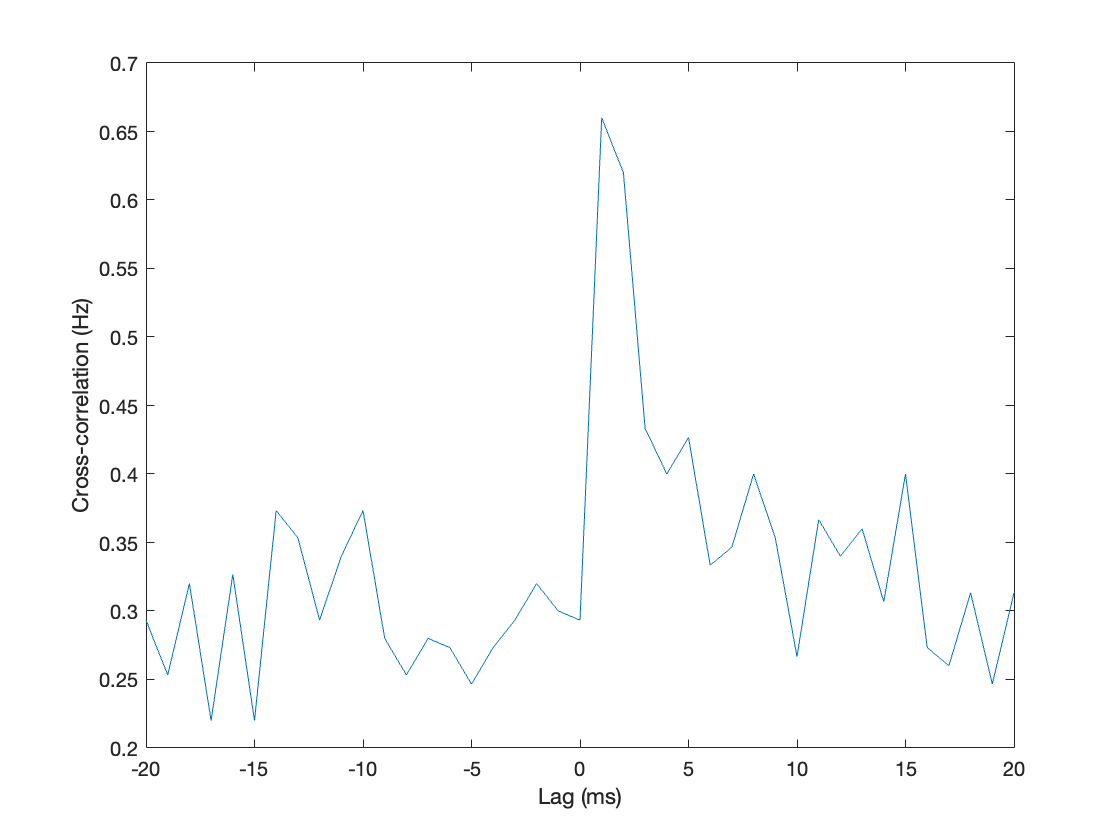

clear all
load prob2.mat
%a)
Nlags = 20;
t = dt*(-Nlags:Nlags);
ccg12 = zeros(length(t),1);
for i = 1:Ntrials
    ccgtemp = calcccg(spikes{1}(:,i),spikes{2}(:,i),Nlags,dt);
    ccg12 = ccg12 + ccgtemp;
end
ccg12 = ccg12/Ntrials;
figure;
plot(1000*t,ccg12);
xlabel('Lag (ms)');
ylabel('Cross-correlation (Hz)');

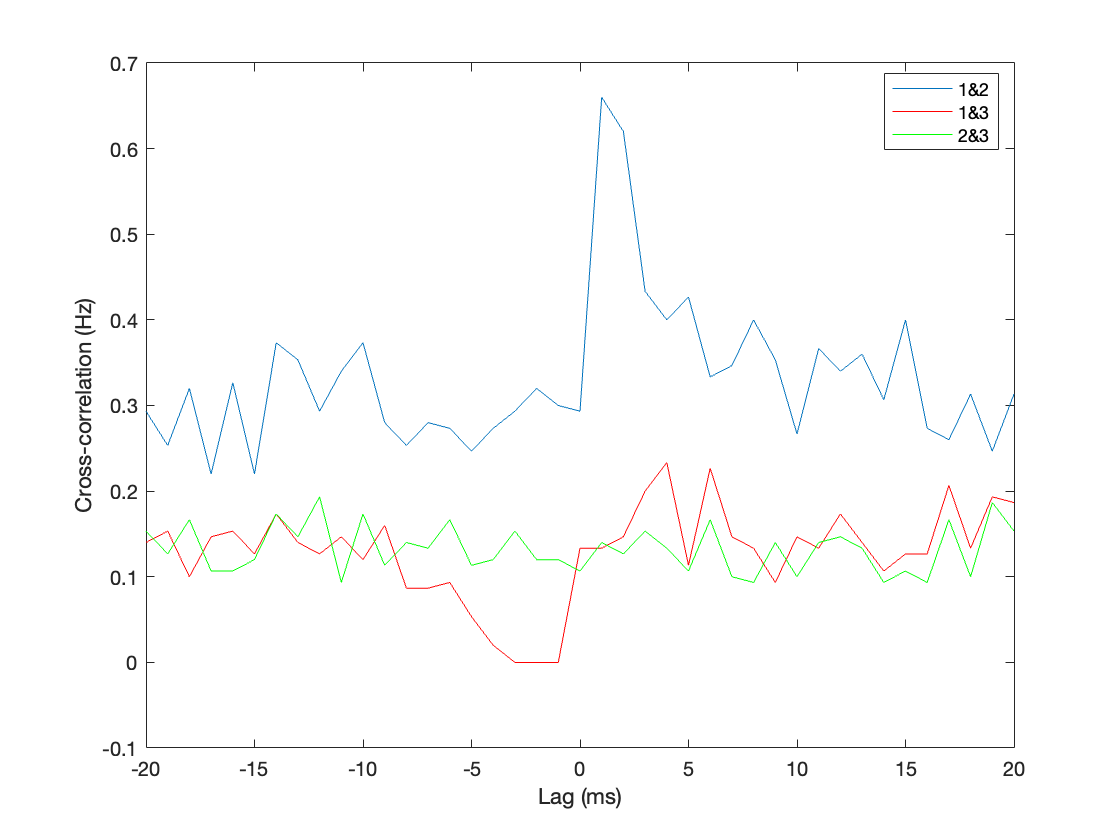


%b)
hold on
ccg13 = zeros(length(t),1);
for i = 1:Ntrials
    ccgtemp = calcccg(spikes{1}(:,i),spikes{3}(:,i),Nlags,dt);
    ccg13 = ccg13 + ccgtemp;
end
ccg13 = ccg13/Ntrials;
plot(1000*t,ccg13,'r-');
ccg23 = zeros(length(t),1);
for i = 1:Ntrials
    ccgtemp = calcccg(spikes{2}(:,i),spikes{3}(:,i),Nlags,dt);
    ccg23 = ccg23 + ccgtemp;
end
ccg23 = ccg23/Ntrials;
plot(1000*t,ccg23,'g-');
legend('1&2','1&3','2&3','location','best')

%1&2 seem to have synaptic connection

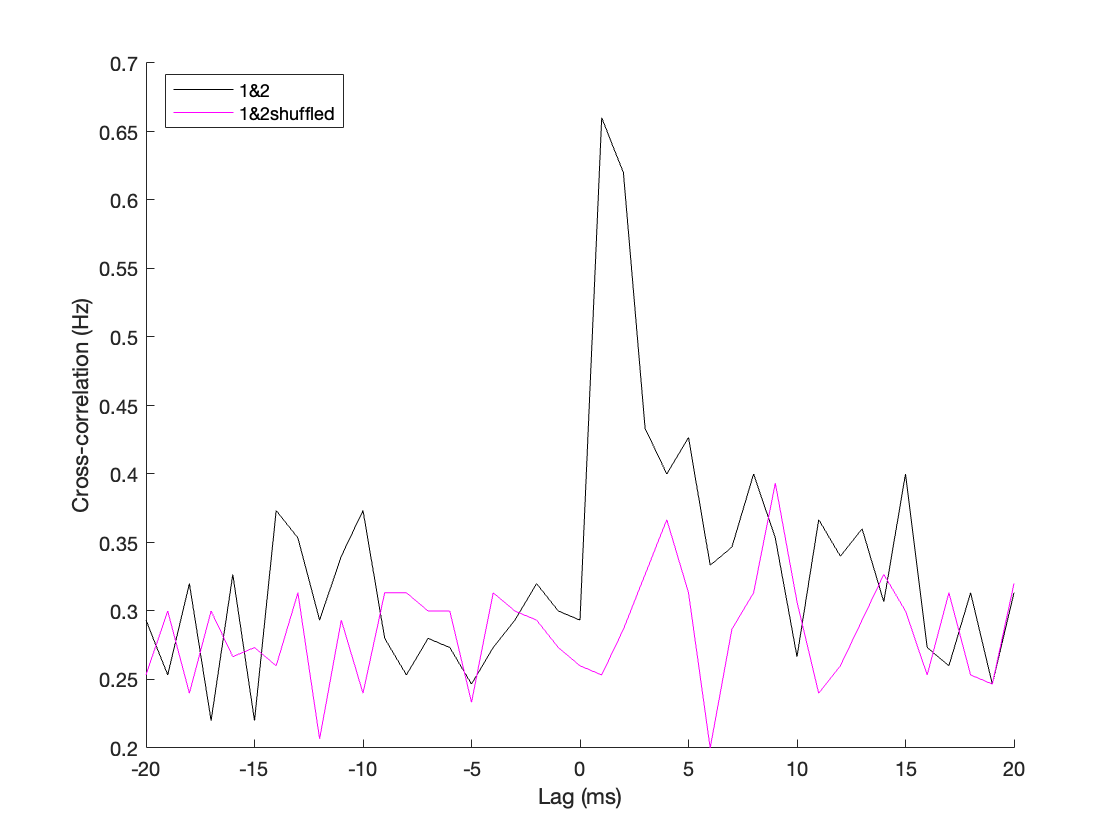

%c)
shufindex = randperm(Ntrials);
ccg12shuf = zeros(length(t),1);
for i = 1:Ntrials
    ccgtemp = calcccg(spikes{1}(:,i),spikes{2}(:,shufindex(i)),Nlags,dt);
    ccg12shuf = ccg12shuf + ccgtemp;
end
ccg12shuf = ccg12shuf/Ntrials;
figure;
hold on
plot(1000*t,ccg12,'k-');
xlabel('Lag (ms)');
ylabel('Cross-correlation (Hz)');
plot(1000*t,ccg12shuf,'m-')
legend('1&2','1&2shuffled','location','best')